close all;

info = obj.TrialInfo;

id_ctrl_l = find(info.Label=="Control" & info.Cued==0 & info.PortCorrect=="L" & info.HD>0.5);
id_ctrl_r = find(info.Label=="Control" & info.Cued==0 & info.PortCorrect=="R" & info.HD>0.5);
id_chemo_l = find(info.Label=="Chemo" & info.Cued==0 & info.PortCorrect=="L" & info.HD>0.5);
id_chemo_r = find(info.Label=="Chemo" & info.Cued==0 & info.PortCorrect=="R" & info.HD>0.5);

id_l = [id_ctrl_l; id_chemo_l];
id_l_shuffle = id_l(randperm(length(id_l)));



figure('Visible', 'on');
hold on;

fill(1000*[0 obj.TaskFP obj.TaskFP 0], [0 0 2 2], 'r', 'FaceColor', 'm', 'FaceAlpha', .1, 'EdgeColor', 'none');

for i = 1:length(id_l)

    i_trial = id_l_shuffle(i);
    switch info.Label(i_trial)
        case 'Control'
            i_color = GPSColor.Control;
        case 'Chemo'
            i_color = GPSColor.Treat;
    end

    plot(obj.TimeFromIn{i_trial}, obj.SpeedHead{i_trial}, 'Color', [i_color .04], 'LineWidth', 2);

end

SpeedHead_median_ctrl_l = median(obj.SpeedHeadMatIn(id_ctrl_l, sum(~isnan(obj.SpeedHeadMatIn(id_ctrl_l,:)))>10), 'omitnan')

SpeedHead_median_ctrl_l =     1.1592    1.1632    1.1692    1.1718    1.1782    1.1852    1.1905    1.1943    1.2003    1.2035    1.2083    1.2152    1.2179    1.2229    1.2313    1.2348    1.2404    1.2463    1.2534    1.2583    1.2616    1.2614    1.2589    1.2574    1.2577    1.2617    1.2629    1.2626    1.2635    1.2629    1.2653    1.2644    1.2650    1.2620    1.2616    1.2638    1.2607    1.2572    1.2536    1.2509    1.2440    1.2390    1.2337    1.2275    1.2202    1.2135    1.2054    1.1976    1.1894    1.1857


SpeedHead_median_ctrl_l = smoothdata(SpeedHead_median_ctrl_l, "gaussian", 100);

SpeedHead_median_chemo_l = median(obj.SpeedHeadMatIn(id_chemo_l, sum(~isnan(obj.SpeedHeadMatIn(id_chemo_l,:)))>10), 'omitnan')

SpeedHead_median_chemo_l =     0.9115    0.9158    0.9198    0.9236    0.9274    0.9318    0.9339    0.9381    0.9419    0.9444    0.9468    0.9493    0.9519    0.9550    0.9580    0.9611    0.9650    0.9688    0.9712    0.9745    0.9746    0.9773    0.9789    0.9785    0.9791    0.9792    0.9779    0.9786    0.9805    0.9800    0.9778    0.9781    0.9775    0.9763    0.9750    0.9738    0.9725    0.9721    0.9721    0.9721    0.9693    0.9659    0.9625    0.9594    0.9547    0.9503    0.9454    0.9411    0.9389    0.9386


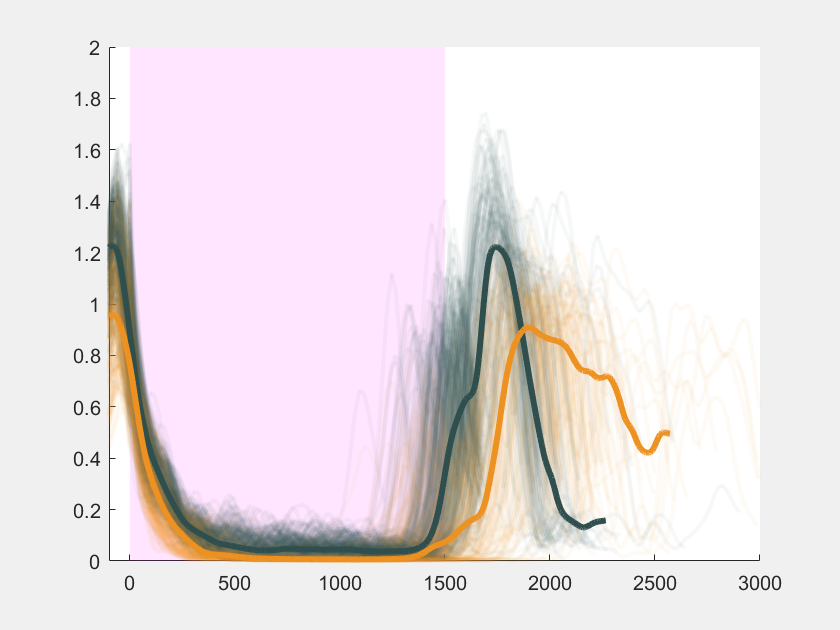

SpeedHead_median_chemo_l = smoothdata(SpeedHead_median_chemo_l, "gaussian", 100);

plot(obj.TimeMatIn(sum(~isnan(obj.SpeedHeadMatIn(id_ctrl_l,:)))>10), SpeedHead_median_ctrl_l, 'Color', GPSColor.Control, 'LineWidth', 3);
plot(obj.TimeMatIn(sum(~isnan(obj.SpeedHeadMatIn(id_chemo_l,:)))>10), SpeedHead_median_chemo_l, 'Color', GPSColor.Treat, 'LineWidth', 3);

xlim([min(obj.TimeMatIn) max(obj.TimeMatIn)])

figure('Visible', 'on');
hold on;

fill(-1000*[0 obj.TaskFP obj.TaskFP 0], [0 0 2 2], 'r', 'FaceColor', 'm', 'FaceAlpha', .1, 'EdgeColor', 'none');
for i = 1:length(id_l)

    i_trial = id_l_shuffle(i);
    switch info.Label(i_trial)
        case 'Control'
            i_color = GPSColor.Control;
        case 'Chemo'
            i_color = GPSColor.Treat;
    end

    plot(obj.TimeFromOut{i_trial}, obj.SpeedHead{i_trial}, 'Color', [i_color .04], 'LineWidth', 2);

end

SpeedHead_median_ctrl_l = median(obj.SpeedHeadMatOut(id_ctrl_l, sum(~isnan(obj.SpeedHeadMatOut(id_ctrl_l,:)))>10), 'omitnan')

SpeedHead_median_ctrl_l =     0.9932    0.9870    0.9771    0.9765    0.9759    0.9739    0.9720    0.9697    0.9655    0.9613    0.9158    0.9069    0.8639    0.8622    0.8606    0.8589    0.8572    0.8556    0.8539    0.8523    0.8736    0.8995    0.9040    0.9270    0.9306    0.9342    0.9343    0.9288    0.9313    0.9358    0.9522    0.9449    0.9500    0.9553    0.9596    0.9572    0.9548    0.9523    0.9499    0.9845    0.9881    0.9908    0.9932    0.9956    1.0112    1.0003    1.0205    1.0252    1.0074    1.0300


SpeedHead_median_ctrl_l = smoothdata(SpeedHead_median_ctrl_l, "gaussian", 100);

SpeedHead_median_chemo_l = median(obj.SpeedHeadMatOut(id_chemo_l, sum(~isnan(obj.SpeedHeadMatOut(id_chemo_l,:)))>10), 'omitnan')

SpeedHead_median_chemo_l =     0.7465    0.7470    0.7474    0.7254    0.7248    0.7241    0.7235    0.7228    0.7222    0.7215    0.7210    0.7213    0.7216    0.7218    0.7221    0.7224    0.7227    0.7402    0.7439    0.7476    0.7513    0.7550    0.7587    0.7623    0.7636    0.7644    0.7653    0.7662    0.7671    0.7680    0.7689    0.7712    0.7743    0.7773    0.7803    0.7874    0.7900    0.7959    0.7981    0.8002    0.8002    0.8015    0.8046    0.8076    0.8344    0.8383    0.8422    0.8461    0.8501    0.8539


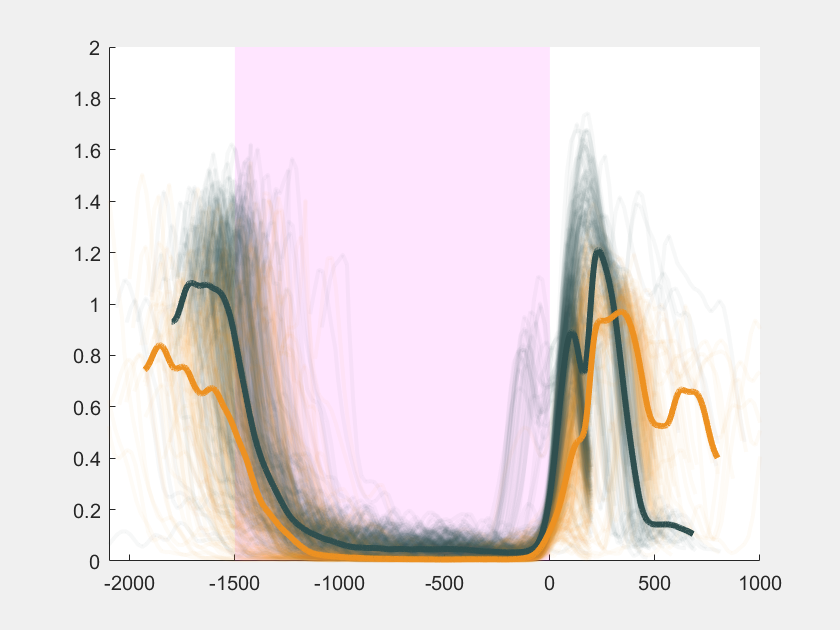

SpeedHead_median_chemo_l = smoothdata(SpeedHead_median_chemo_l, "gaussian", 100);

plot(obj.TimeMatOut(sum(~isnan(obj.SpeedHeadMatOut(id_ctrl_l,:)))>10), SpeedHead_median_ctrl_l, 'Color', GPSColor.Control, 'LineWidth', 3);
plot(obj.TimeMatOut(sum(~isnan(obj.SpeedHeadMatOut(id_chemo_l,:)))>10), SpeedHead_median_chemo_l, 'Color', GPSColor.Treat, 'LineWidth', 3);

xlim([min(obj.TimeMatOut) max(obj.TimeMatOut)])

figure('Visible', 'on');
hold on;

fill([0 1 1 0], [0 0 2 2], 'r', 'FaceColor', 'm', 'FaceAlpha', .1, 'EdgeColor', 'none');
for i = 1:length(id_l)

    i_trial = id_l_shuffle(i);
    switch info.Label(i_trial)
        case 'Control'
            i_color = GPSColor.Control;
        case 'Chemo'
            i_color = GPSColor.Treat;
    end

    plot(obj.TimeWarped{i_trial}, obj.SpeedHead{i_trial}, 'Color', [i_color .04], 'LineWidth', 2);

end

SpeedHead_median_ctrl_l = median(obj.SpeedHeadMatWarp(id_ctrl_l, sum(~isnan(obj.SpeedHeadMatWarp(id_ctrl_l,:)))>10), 'omitnan')

SpeedHead_median_ctrl_l =     1.0674    1.0756    1.0837    1.0919    1.1216    1.0901    1.0593    1.0761    1.0669    1.0557    1.0647    1.0668    1.0729    1.0726    1.0721    1.0817    1.0867    1.0906    1.0960    1.0992    1.1024    1.1068    1.1128    1.1213    1.1303    1.1353    1.1424    1.1509    1.1573    1.1638    1.1710    1.1773    1.1863    1.1935    1.2022    1.2129    1.2181    1.2270    1.2341    1.2392    1.2443    1.2483    1.2562    1.2600    1.2628    1.2638    1.2666    1.2662    1.2650    1.2635


SpeedHead_median_ctrl_l = smoothdata(SpeedHead_median_ctrl_l, "gaussian", 100);

SpeedHead_median_chemo_l = median(obj.SpeedHeadMatWarp(id_chemo_l, sum(~isnan(obj.SpeedHeadMatWarp(id_chemo_l,:)))>10), 'omitnan')

SpeedHead_median_chemo_l =     0.8545    0.8920    0.9174    0.9480    0.9552    0.9036    0.9038    0.8993    0.9081    0.9036    0.9100    0.9157    0.9148    0.9160    0.9220    0.9253    0.9180    0.8954    0.8985    0.8894    0.8863    0.8890    0.8915    0.8914    0.8944    0.8942    0.8933    0.8891    0.8879    0.8933    0.9010    0.9049    0.9090    0.9096    0.9109    0.9172    0.9200    0.9211    0.9260    0.9312    0.9363    0.9378    0.9473    0.9541    0.9573    0.9592    0.9625    0.9631    0.9643    0.9670


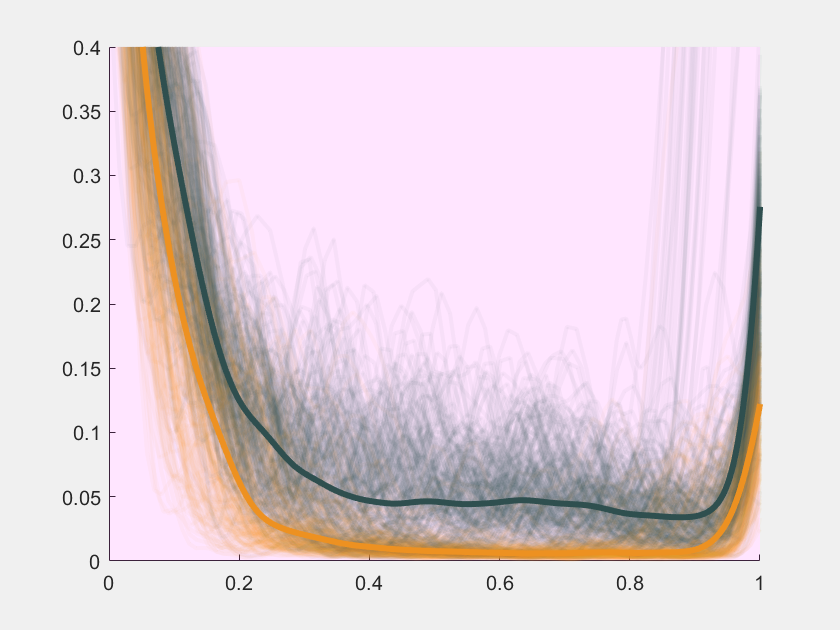

SpeedHead_median_chemo_l = smoothdata(SpeedHead_median_chemo_l, "gaussian", 100);

plot(obj.TimeMatWarp(sum(~isnan(obj.SpeedHeadMatWarp(id_ctrl_l,:)))>10), SpeedHead_median_ctrl_l, 'Color', GPSColor.Control, 'LineWidth', 3);
plot(obj.TimeMatWarp(sum(~isnan(obj.SpeedHeadMatWarp(id_chemo_l,:)))>10), SpeedHead_median_chemo_l, 'Color', GPSColor.Treat, 'LineWidth', 3);

xlim([0 1]); ylim([0 0.4])

figure('Visible', 'on');
hold on;

% fill([0 1 1 0], [0 0 2 2], 'r', 'FaceColor', 'm', 'FaceAlpha', .1, 'EdgeColor', 'none');
for i = 1:length(id_l)

    i_trial = id_l_shuffle(i);
    switch info.Label(i_trial)
        case 'Control'
            i_color = GPSColor.Control;
        case 'Chemo'
            i_color = GPSColor.Treat;
    end

    plot(obj.TimeWarped{i_trial}, obj.AccHead{i_trial}, 'Color', [i_color .04], 'LineWidth', 2);

end

AccHead_median_ctrl_l = median(obj.AccHeadMatWarp(id_ctrl_l, sum(~isnan(obj.AccHeadMatWarp(id_ctrl_l,:)))>10), 'omitnan')

AccHead_median_ctrl_l =     0.0387    0.0406    0.0396    0.0385    0.0377    0.0404    0.0395    0.0402    0.0412    0.0418    0.0419    0.0423    0.0414    0.0414    0.0408    0.0401    0.0390    0.0383    0.0372    0.0361    0.0351    0.0342    0.0333    0.0321    0.0309    0.0298    0.0287    0.0278    0.0266    0.0255    0.0243    0.0233    0.0223    0.0212    0.0202    0.0190    0.0179    0.0169    0.0159    0.0149    0.0142    0.0135    0.0131    0.0127    0.0122    0.0119    0.0115    0.0111    0.0106    0.0102


AccHead_median_ctrl_l = smoothdata(AccHead_median_ctrl_l, "gaussian", 100);

AccHead_median_chemo_l = median(obj.AccHeadMatWarp(id_chemo_l, sum(~isnan(obj.AccHeadMatWarp(id_chemo_l,:)))>10), 'omitnan')

AccHead_median_chemo_l =     0.0313    0.0325    0.0326    0.0331    0.0329    0.0339    0.0353    0.0337    0.0345    0.0340    0.0332    0.0325    0.0315    0.0306    0.0297    0.0289    0.0291    0.0290    0.0287    0.0280    0.0277    0.0281    0.0272    0.0266    0.0259    0.0252    0.0246    0.0239    0.0231    0.0225    0.0220    0.0213    0.0204    0.0195    0.0187    0.0179    0.0172    0.0163    0.0156    0.0148    0.0141    0.0134    0.0127    0.0121    0.0116    0.0111    0.0105    0.0101    0.0096    0.0092


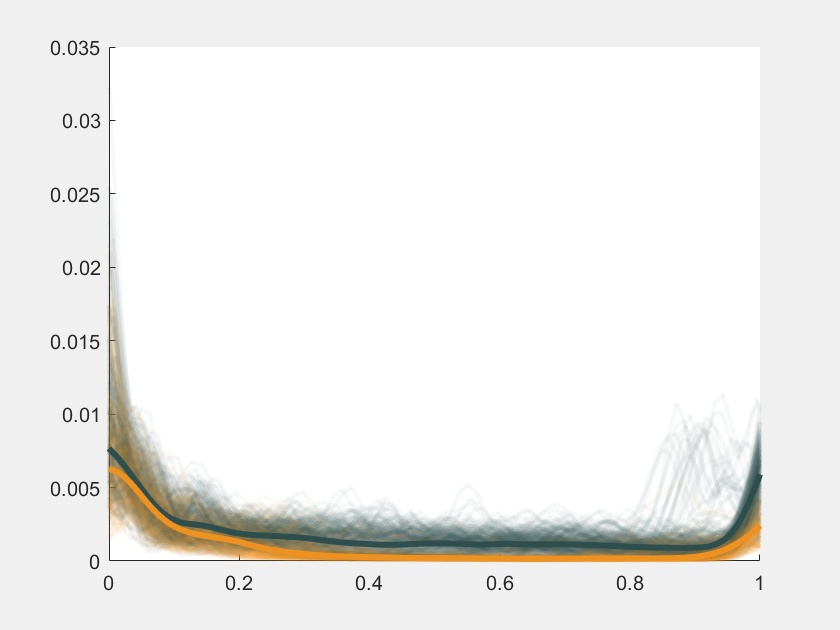

AccHead_median_chemo_l = smoothdata(AccHead_median_chemo_l, "gaussian", 100);

plot(obj.TimeMatWarp(sum(~isnan(obj.AccHeadMatWarp(id_ctrl_l,:)))>10), AccHead_median_ctrl_l, 'Color', GPSColor.Control, 'LineWidth', 3);
plot(obj.TimeMatWarp(sum(~isnan(obj.AccHeadMatWarp(id_chemo_l,:)))>10), AccHead_median_chemo_l, 'Color', GPSColor.Treat, 'LineWidth', 3);

xlim([0 1])


1000*mean(obj.AccHeadMatWarp(id_ctrl_l,900))

ans = 1.1956

1000*std(obj.AccHeadMatWarp(id_ctrl_l,900))/sqrt(length(id_ctrl_l))*1.96

ans = 0.0767


1000*mean(obj.AccHeadMatWarp(id_chemo_l,900))

ans = 0.2056

1000*std(obj.AccHeadMatWarp(id_chemo_l,900))/sqrt(length(id_chemo_l))*1.96

ans = 0.0282